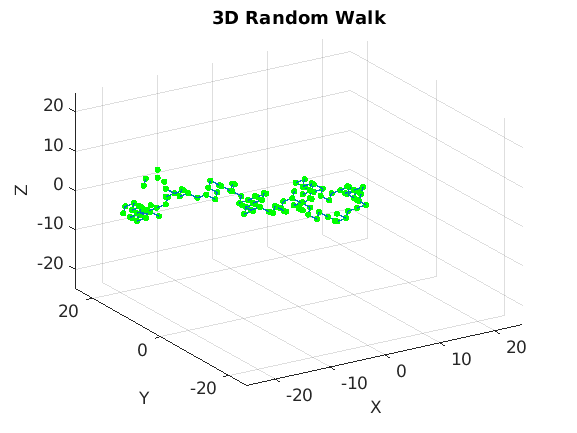

clc
close all;
clear all;
clear x
probability=0.50; %probabilidad de si la decisión es +1 o -1 en Y en el rango de 0 a 1
step=1; %numero de pasos
T=200; %Cantidad de situaciones o tiempo de 0 a 100
x(1)=0; %punto de partida
y(1)=0;
z(1)=0;
figure(1)
for i=2:T %loop de conteos
    if (rand > probability) %Si el randomizador es mayor a la probabilidad entonces....
        x(i)=x(i-1)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.50 entonces +1
    else
        x(i)=x(i-1)-step; % de lo contrario -1       
    end
    if (rand > probability)
        y(i)=y(i-1)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.50 entonces +1
    else
        y(i)=y(i-1)-step; % de lo contrario -1       
    end
    if (rand > probability)
        z(i)=z(i-1)+step; %como se tiene un rango de 0 a 100 con probabilidad de 0.50 entonces +1
    else
        z(i)=z(i-1)-step; % de lo contrario -1       
    end
        plot3(x,y,z,'.','Markersize',10,'MarkerEdgeColor','green')
         hold on
         line([x(i-1) x(i)], [y(i-1) y(i)],[z(i-1) z(i)],'linewidth',1);
         axis([ -25 25 -25 25 -25 25]);
         view([-32 30]);
         grid on
         h=gca; 
         get(h,'fontSize');
         set(h,'fontSize',12);
         xlabel('X','fontSize',12);
         ylabel('Y','fontSize',12);
         zlabel('Z','fontSize',12);
         title('3D Random Walk','fontsize',14)
         fh = figure(1);
         set(fh, 'color', 'white'); 
         F=getframe;
end 
      movie(F)

### **Análisis:**

Al algoritmo presentado pretende simular los "caminos aleatorios" en tres dimesiones de la siguiente manera.

Para comenzar, la definición de las variables:

- -Se define la variable "p", que define la probabilidad en la que serán acotados los casos explicados más adelante. La variable será generada a través de la función "rand", según la cual, el comportamiento de la gráfica variará.

- -Se define la variable "step", que equivale al valor unitario que será adicionado o restado según la probabilidad que haya sido originada a través de la función "rand".

- -Se devine "T", como el eje x de la gráfica, el cual representa el tiempo de ejecución, simulando que cada "step" desde el valor de partida hasta "T", equivale al paso del tiempo total de ejecución.

- Se inicializan x,y,z en 0 para definir el punto de partida que se va a tomar.

#### Explicación de los ciclos "for"

- -El primer bucle for será el encargado de generar las múltiples trayectorias a través de la variable "line", que para este código se ha definido desde 1 hasta 5, siendo que serán graficados 5 caminos aleatorios.

- -El segundo bucle for será el que decida a través de la función "rand" y 2 condiciones, la adición o sustracción del valor inicial de la variable respuesta de la siguiente forma:

1. "rand" genera un valor aleatorio que será comparado con la variable "p", en dado caso de que el valor aleatorio sea mayor a "p", se cumple el primer caso en el que a la variable de partida le será adicionado el valor de "step". En el caso contrario,

2. Si "rand" genera un valor aleatorio menor a "p", cumpliendo el segundo caso, a la variable de partida le será sustraído el valor de "step".

Este bucle for se llevará a cabo hasta que se hayan completado los 100 casos estipulados para "T".

Cuando el bucle interno for termine, el bucle exterior for cambiará repetidas veces hasta generar los múltiples caminos aleatorios según la regla del for interno. Cabe resaltar que esto se hará posteriormente para los valores de y, y z de tal manera que el loop se haga repeditas veces para que así pueda crearse el respectivo camino aleatorio para dicho algoritmo. Finalmente se plotean los puntos y se diseñan los parametros de lo que irá en la gráfica